# Generating Swing-Free Maneuvers for Simple Gantry Crane System

In this demo, we use optimization to find optimal bang-coast-bang acceleration basis functions. Acceleration function is calculated to minimize swing of payload. Dynamic equations used are for a simplified Gantry Crane System and are derived using Symbolic Math Toolbox.

## Cart Acceleration Profile

The following shows the accleration profile of the crane cart. The goal is to find the optimal values for time variables, tp1, tp2, and tf.

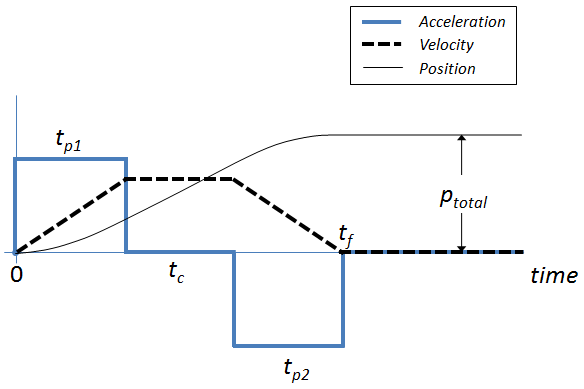

## Set Initial Values

With a particular set of initial values, we get the following behavior.

r       = 20;  % height of crane (m)
ptotal  = 40;  % payload displacement (m)
tp1_org = 4.5;   % length of first pulse (sec)
tp2_org = 4.5;   % length of second pulse (sec)
tf_org  = 19.;  % total length of time (sec)

sol = solveCraneODE([tp1_org, tp2_org, tf_org]', ptotal, r);
plotResult(sol);

## Animate

figure('Visible','on');
animateCrane(sol)

## Setup and Run the Optimization

To run the following optimization, you need Optimization Toolbox.

We define the following constraints:

- tf >= tp1 + tp2

- 1 <= tp1 <= 15 (in seconds)

- 1 <= tp2 <= 15 (in seconds)

- 4 <= tpf <= 20 (in seconds)

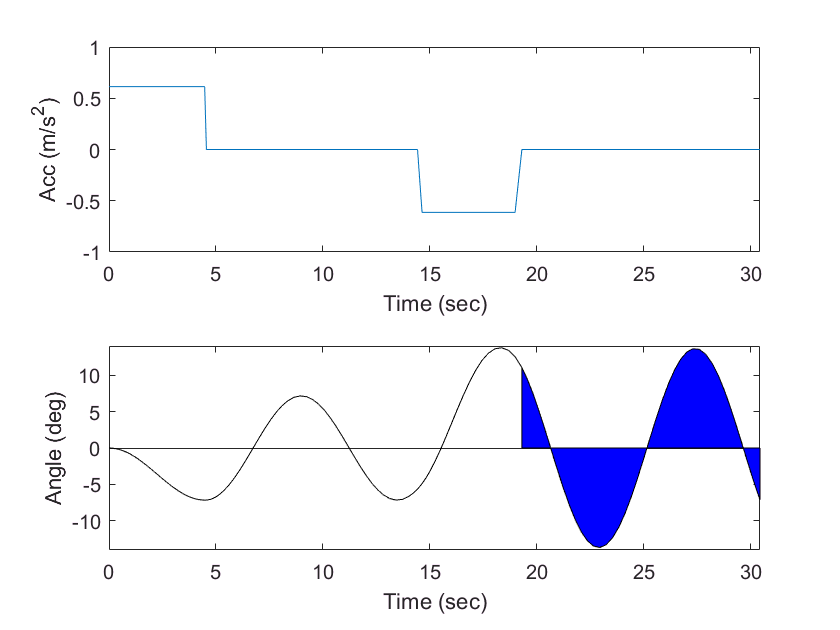

A = [1, 1, -1];
b = 0;
x0 = [tp1_org, tp2_org, tf_org]';
lb = [1, 1, 4];
ub = [15, 15, 20];


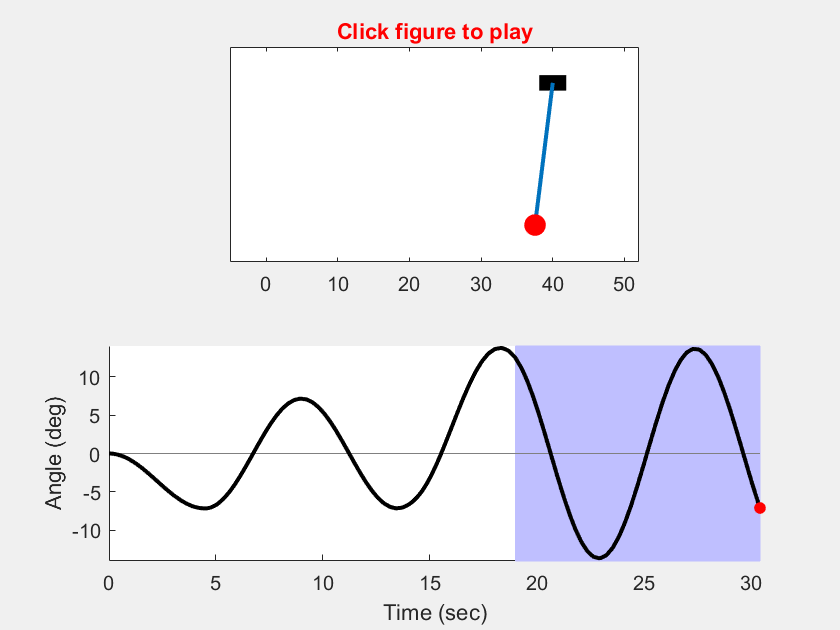

options = optimset;
% options = optimset(options,'Display' ,'iter');
options = optimset(options, 'Algorithm', 'interior-point');


x = fmincon(@(x) swingCalc(x, ptotal, r), x0, A, b, ...
   [], [], lb, ub, [], options);

## Display Output from Optimization

solOptim = solveCraneODE(x, ptotal, r);
plotResult(solOptim);

## Animate

figure('Visible','on');
animateCrane(solOptim)

## Run with Multiple Starting Points

This problem contains multiple solutions that are acceptable. So we want to make sure that we haven't missed other (better) solutions. One way to do that is to solve the optimization problem with different initial conditions. With *Global Optimization Toolbox*, you can use the "MultiStart" solve to automate this process.

p = parpool(2);  % run in parallel for performance

opts = optimset;
opts = optimset(opts, 'Algorithm', 'interior-point');
problem = createOptimProblem('fmincon','objective',...
    @(x) swingCalc(x, ptotal, r), ...
    'x0', x, 'Aineq', A, 'bineq', b, ...
    'lb', lb, 'ub', ub, 'options', opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    1.613707e+00    0.000e+00    1.320e-01
    1       8    1.545439e+00    0.000e+00    1.333e-01    2.190e-01
    2      12    1.315941e+00    0.000e+00    8.855e-02    9.819e-01
    3      16    1.203916e+00    0.000e+00    7.752e-02    6.211e-01
    4      20    1.088469e+00    0.000e+00    5.274e-02    6.782e-01
    5      24    8.150638e-01    0.000e+00    8.043e-02    1.145e+00
    6      28    3.769530e-01    0.000e+00    2.048e-02    1.501e+00
    7      32    1.777856e-01    0.000e+00    5.311e-03    6.320e-01
    8      36    8.154927e-02    0.000e+00    1.933e-03    3.909e-01
    9      40    3.158516e-02    0.000e+00    5.498e-03    2.524e-01
   10      44    5.938688e-03    0.000e+00    9.863e-03    1.742e-01
   11      61    5.446455e-03    0.000e+00    1.715e-02    9.488e-04
   12      66    5.174088e-03    0.000e+00    9

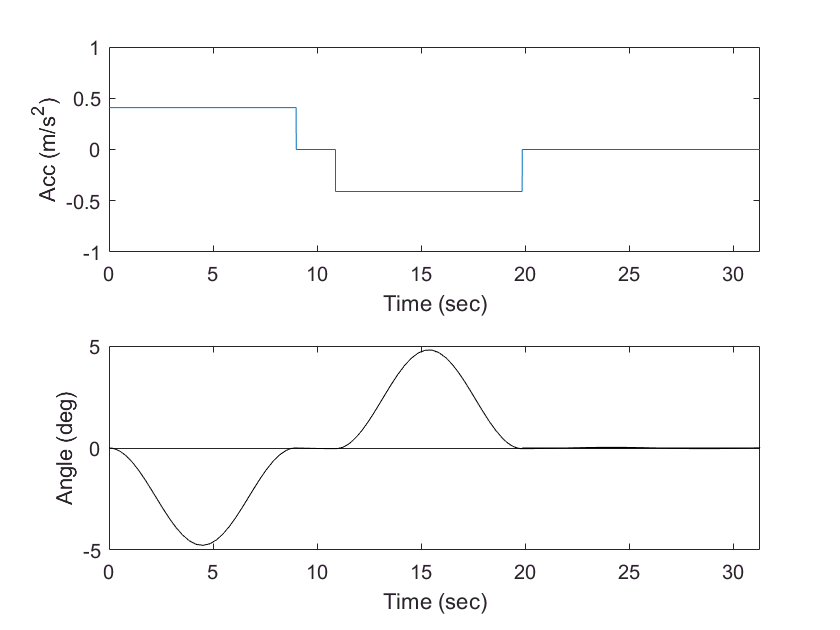


 % 8 different initial conditions

 pts = [...

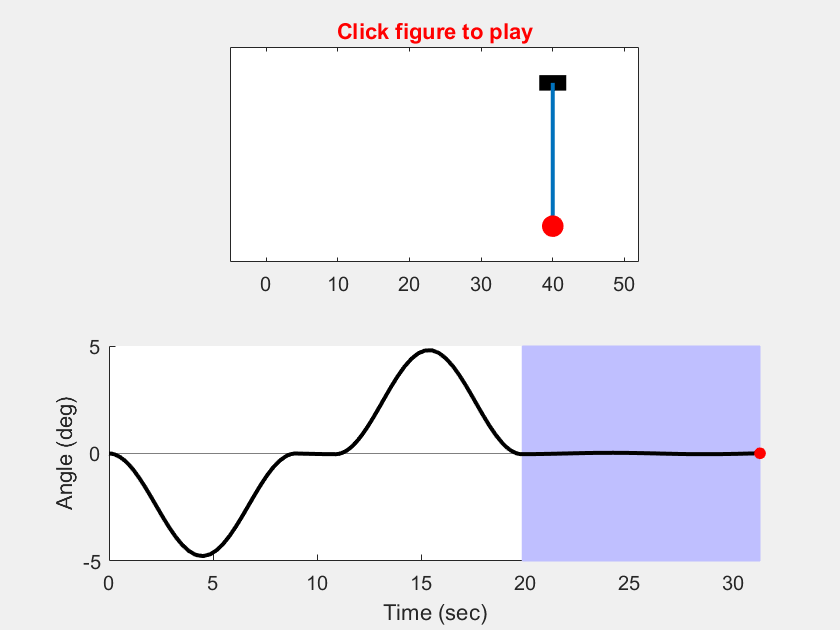

    1  1  4;
    1  9  10;
    2  18 20;
    18 2  20;

    10 2  20;
    2  10 20;
    6  6  15;
    7  7  16];


start_pts = CustomStartPointSet(pts);
ms = MultiStart('UseParallel', 'always', 'Display' ,'iter');  % for parallel
[xMS, ~, ~, ~, allSol]  = run(ms, problem, start_pts);

## Find Top 3 Possible Solutions and Plot

Notice different solutions resulted from different initial guesses.

totalSol = [allSol.X]; totalSol = totalSol(:,1:3);
solMS = solveCraneODE(totalSol, ptotal, r);
plotResult(solMS)

## Animate Top 3 Solutions

% animateCrane(solMS(1))
% animateCrane(solMS(2))
animateCrane(solMS(3))

## Applying Additional Constraints

We see that while the payload is kept steady after completion, some of the solutions result in large oscillations during the motion. Let's also restrict maximum amplitude to be less than +-5 degrees during total swing. We'll do that by adding an additional nonlinear constraint to the problem.

maxAng = 5; % Maximum angle of pendulum
problemNew = createOptimProblem('fmincon','objective',...
    @(x) swingCalc(x, ptotal, r), ...
    'x0', x, 'Aineq', A, 'bineq', b, ...
    'lb', lb, 'ub', ub, 'options', opts, ...
    'nonlcon',@(x) swingMagConst(x, ptotal, r, maxAng));

% Run MultiStart with the start_pts cell array:
msNew = MultiStart('UseParallel', 'always', 'Display', 'iter');  % for parallel
[xMSNew, ~, ~, ~, allSolNew] = run(msNew, problemNew, start_pts);

delete(p)  % close pool of workers when finished

## Find Top 3 Possible New Solutions and Plot

Notice that in the new set of solutions, the pendulum swing is limited to under 5 degrees.

totalSolNew = [allSolNew.X]; totalSolNew = totalSolNew(:,1:3);
solMSNew = solveCraneODE(totalSolNew, ptotal, r);
plotResult(solMSNew)

## Animate Top 3 Solutions

animateCrane(solMSNew(1))
% animateCrane(solMSNew(2))
% animateCrane(solMSNew(3))

*Copyright 2017 The MathWorks, Inc.*